clear;

% phase lead rlocus 방법
ess = 0.05;
zeta = 0.4

zeta = 0.4000

Ts = 1;

Kv = 1/ess

Kv = 20

wn = 4/(Ts*zeta)

wn = 10


s = tf('s');
G = 40/(s*(s+2))

G =
 
     40
  ---------
  s^2 + 2 s
 
연속시간 전달 함수입니다.
모델 속성


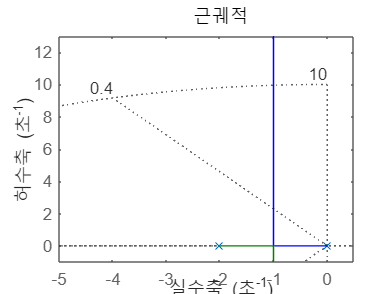


rlocus(G);
axis([-5 0.5 -1 13]);
sgrid(zeta,wn);


z0 = -zeta*wn

z0 = -4

desired_root = z0 + 1i*sqrt(wn^2 - z0^2)

desired_root = -4.0000 + 9.1652i


ang_p0 = pi - (sum(angle(desired_root - pole(G))) - angle(desired_root - z0))

ang_p0 = 0.9444

p0 = z0 - imag(desired_root)/tan(ang_p0)

p0 = -10.6316

Gc = (s-z0)/(s-p0)

Gc =
 
    s + 4
  ---------
  s + 10.63
 
연속시간 전달 함수입니다.
모델 속성


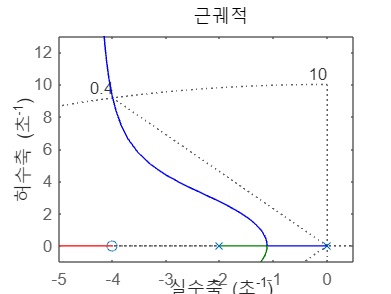


rlocus(Gc*G)
axis([-5 0.5 -1 13]);
sgrid(zeta,wn);

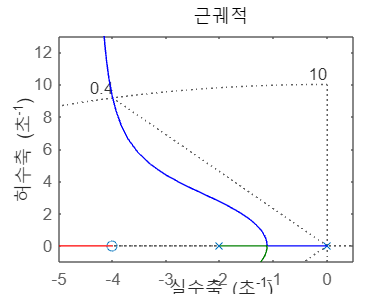


rlocus(Gc*G)
axis([-5 0.5 -1 13]);
sgrid(zeta,wn);


K = rlocfind(Gc*G,desired_root)

K = 2.8947

Gc = K*Gc

Gc =
 
  2.895 s + 11.58
  ---------------
     s + 10.63
 
연속시간 전달 함수입니다.
모델 속성


Kv = dcgain(Gc*G*s)

Kv = 21.7822


sys_cl = feedback(Gc*G,1)

sys_cl =
 
           115.8 s + 463.2
  ---------------------------------
  s^3 + 12.63 s^2 + 137.1 s + 463.2
 
연속시간 전달 함수입니다.
모델 속성


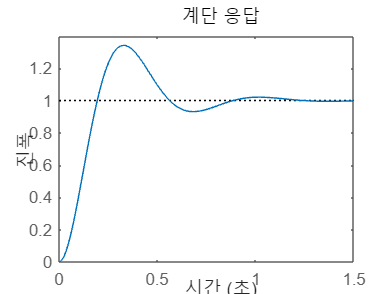


step(sys_cl)

stepinfo(sys_cl)

ans = 다음 필드를 포함한 struct :
         RiseTime: 0.1319
    TransientTime: 1.0522
     SettlingTime: 1.0522
      SettlingMin: 0.9314
      SettlingMax: 1.3420
        Overshoot: 34.1970
       Undershoot: 0
             Peak: 1.3420
         PeakTime: 0.3339


% phase lead bode 방법
clear;

s = tf('s');
G = 40/(s*(s+2));

ess = 0.05;
Kv = 1/ess

Kv = 20

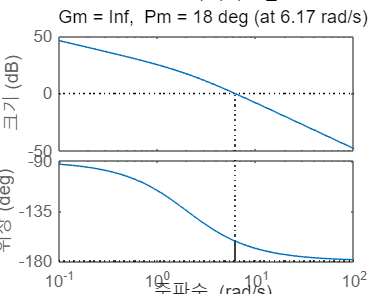

Pm_want = 40;

margin(G)

[Gm, Pm, Wng, Wnp] = margin(G)

Gm = Inf

Pm = 17.9642

Wng = Inf

Wnp = 6.1685

Pm_need = Pm_want - Pm

Pm_need = 22.0358

Pm_need = 30;

syms alpha
eqn_alpha = sin(deg2rad(Pm_need)) == (alpha-1)/(alpha+1)

$$eqn\_alpha = \frac{1}{2}=\frac{\alpha -1}{\alpha +1}$$

alpha = double(solve(eqn_alpha,alpha))

alpha = 3

wm = getGainCrossover(G,1/sqrt(alpha))

wm = 8.2043

z0 = -wm/sqrt(alpha)

z0 = -4.7368

p0 = z0*alpha

p0 = -14.2103


Gc = (s - z0)/(s - p0)

Gc =
 
  s + 4.737
  ---------
  s + 14.21
 
연속시간 전달 함수입니다.
모델 속성


Kv = dcgain(Gc*G*s)

Kv = 6.6667

Gc = Gc*20/Kv

Gc =
 
   20 s + 94.74
  ---------------
  6.667 s + 94.74
 
연속시간 전달 함수입니다.
모델 속성


Kv = dcgain(Gc*G*s)

Kv = 20

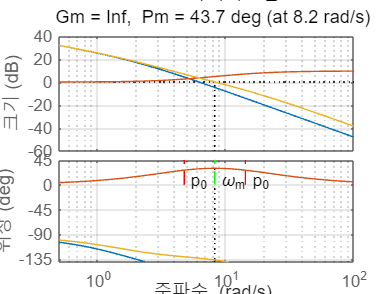

bode(G)

axis([0.5, 100, -140, 45])
grid;

hold on
bode(Gc)
margin(Gc*G)

plot([-z0, -z0], [0, 90], 'r--');
text(-z0*1.1,5,'p_0');
plot([-p0, -p0], [0, 90], 'r--');
text(-p0*1.1, 5, 'p_0');
plot([wm wm], [0, 90], 'g--');
text(wm*1.1, 5, '\omega_m');

hold off

% phase lag rlocus
clear;
s = tf('s');
ess = 0.05 % Kv = 20

ess = 0.0500

zeta = 0.4

zeta = 0.4000


G = 40/(s*(s+2))

G =
 
     40
  ---------
  s^2 + 2 s
 
연속시간 전달 함수입니다.
모델 속성


rlocus(G)
sgrid(zeta,10)
axis([-2.5 0.5 -3 3])

root_real = -1;
theta = acos(zeta);
root_angle = pi-theta;
root_imag = 1i*root_real*tan(root_angle);
root = root_real + root_imag;
K = rlocfind(G,root)

K = 0.1562

Kv = dcgain(G*s*K)

Kv = 3.1250

alpha = 20/Kv

alpha = 6.4000

z0 = -0.1;
p0 = -0.1/alpha;
C_lag = K*(s-z0)/(s-p0)

C_lag =
 
  0.1562 s + 0.01562
  ------------------
     s + 0.01562
 
연속시간 전달 함수입니다.
모델 속성



sys_cl = feedback(G*C_lag,1)

sys_cl =
 
           6.25 s + 0.625
  ---------------------------------
  s^3 + 2.016 s^2 + 6.281 s + 0.625
 
연속시간 전달 함수입니다.
모델 속성


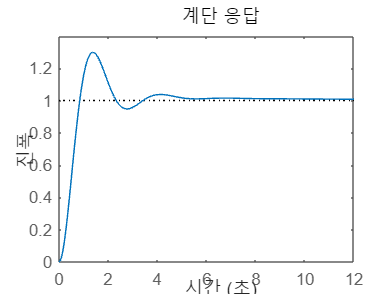

step(sys_cl)

stepinfo(sys_cl)

ans = 다음 필드를 포함한 struct :
         RiseTime: 0.5704
    TransientTime: 4.8815
     SettlingTime: 4.8815
      SettlingMin: 0.9114
      SettlingMax: 1.2983
        Overshoot: 29.8285
       Undershoot: 0
             Peak: 1.2983
         PeakTime: 1.3963


% phase lag rlocus
clear;
s = tf('s');
ess = 0.05 % Kv = 20

ess = 0.0500

Pm_want = 50

Pm_want = 50


G = 40/(s*(s+2))

G =
 
     40
  ---------
  s^2 + 2 s
 
연속시간 전달 함수입니다.
모델 속성


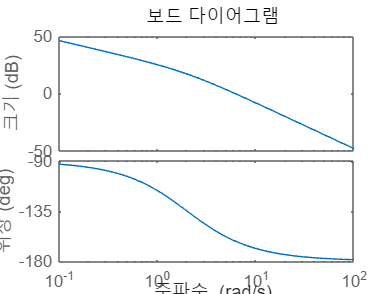

bode(G)

[gm, pm, wg, wp] = margin(G)

gm = Inf

pm = 17.9642

wg = Inf

wp = 6.1685


wc = 1.68;

[mag, phase] = bode(G,wc)

mag = 9.1155

phase = -130.0303


alpha = mag

alpha = 9.1155

z0 = -wc/10

z0 = -0.1680

p0 = z0/alpha

p0 = -0.0184

K = 1/alpha

K = 0.1097


C_lag = K*(s-z0)/(s-p0)

C_lag =
 
  0.1097 s + 0.01843
  ------------------
     s + 0.01843
 
연속시간 전달 함수입니다.
모델 속성


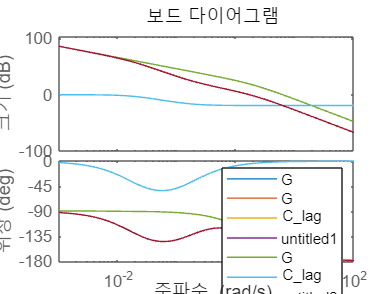

bode(G)
hold on
bode(C_lag)
bode(C_lag*G)